clc; clear; close all;

R = 10;
C = 2;

s = tf('s');

H = 1/(1+R*C*s)

H =
 
     1
  --------
  20 s + 1
 
Continuous-time transfer function.



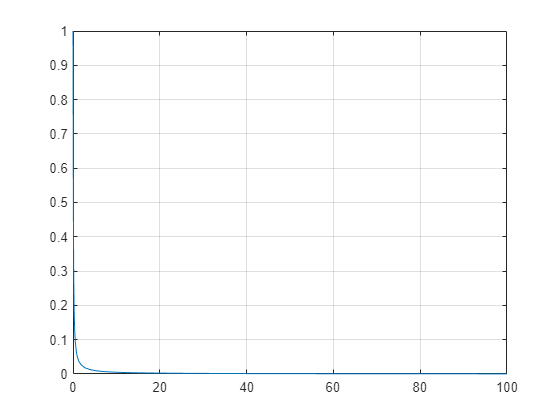

[mag, phase,w] = bode(H, logspace(-5,2));
mag = squeeze(mag);
phase = squeeze(phase);
plot(w,mag)
% Plot on logarithmic scale to make small frequencies as important as large
% frequencies
grid on

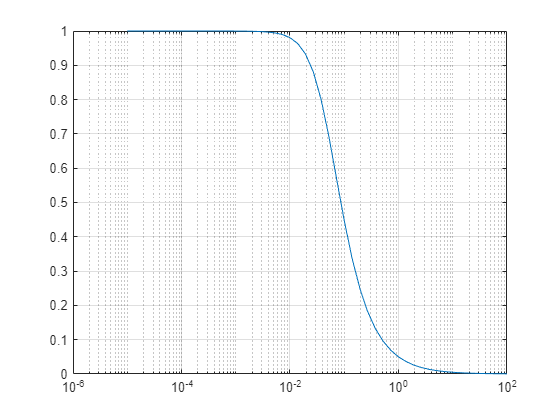

semilogx(w,mag)
grid on

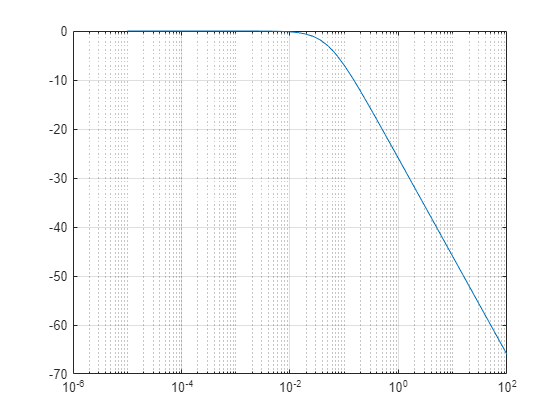

semilogx(w,db(mag))
grid on

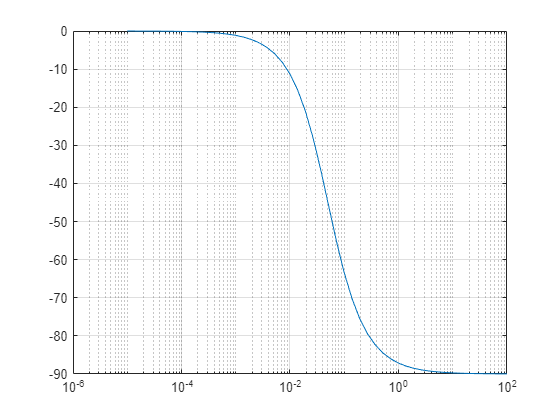

semilogx(w,phase)
grid on

w = 100;
z = 0.1;

H2 = w^2/(s^2 + 2*z*w*s + w^2)

H2 =
 
        10000
  ------------------
  s^2 + 20 s + 10000
 
Continuous-time transfer function.



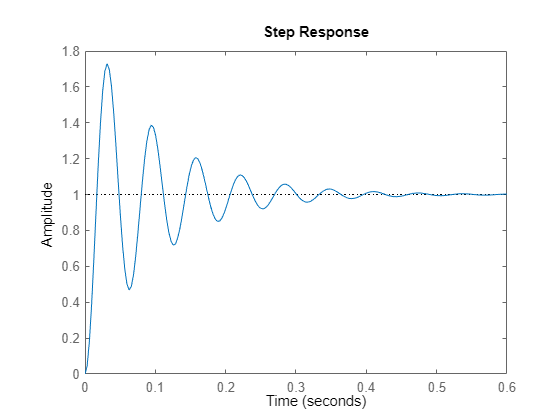

step(H2)

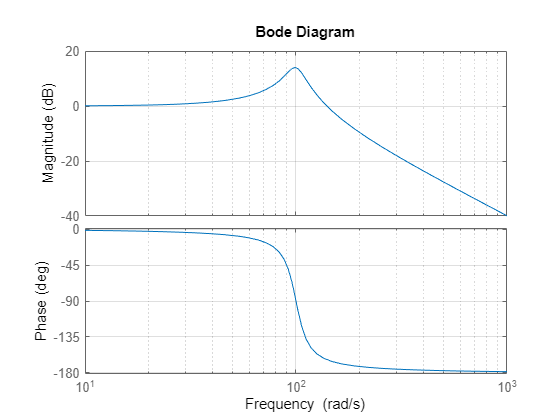

bode(H2)
grid on

H3 = H*H2

H3 =
 
                 10000
  -----------------------------------
  20 s^3 + 401 s^2 + 200020 s + 10000
 
Continuous-time transfer function.



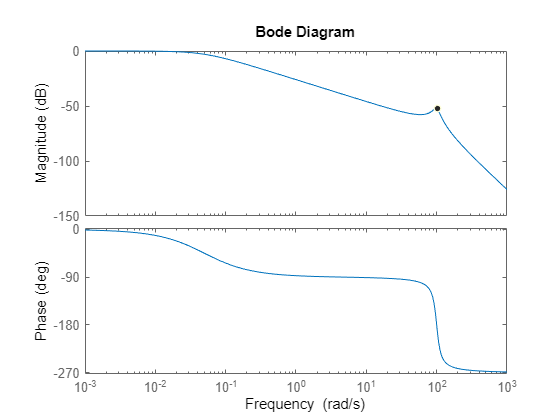

bode(H3)